## **Laboratório 2 - ISC**

Alunos: Guilherme Tsubahara Horstmann e Marcos Davi de Oliveira

Um sistema é linear se atende, simultaneamente, aos princípios da homogeneidade e da aditividade. Caso não atenda a, pelo menos um destes princípios, ele é não linear. Para exercitar o Simulink, proponha experimentos que verifiquem se um sistema é ou não linear, e se é ou não variante no tempo. Para isso, construa os sistemas dados pelas equações abaixo, onde x(t) representa a entrada e y(t), a saída e verifique se estes sistemas são: 

a) Homogêneos/Não-Homogêneos 

b) Aditivos/Não-Aditivos 

c) Lineares/Não-Lineares 

d) Variantes/Invariantes no tempo 

### **Sistema 1**


$$\frac{\mathrm{dy}}{\mathrm{dt}}+2y=x\to \frac{\mathrm{dy}}{\mathrm{dt}}=x-2y$$


A partir disso, conseguimos modelas essa função do simulink.

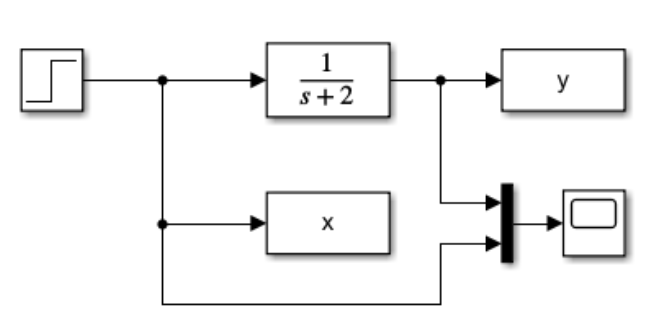

Feito essa modelagem, será verificado a veracidade de cada uns dos itens da questão.

#### **a) Homogêneos/Não-Homogêneos**

Para verificarmos esse item, precisamos criar diversos casos e ver como o modelo se comporta em cada um deles. Deste modo, usamos o bloco "Multiport Switch", denotado por "Switch Case". Nele é dado 5 entradas e tem apenas uma saída. O primeiro pino controla qual entrada será realmente utilizada no modelo. Os pinos 1, 2, 3, 4 e 5 são pinos de entrada, sendo que o primeiro pino tem um step de 1, o segundo pino de um step de 2, o terceiro pino tem um step de 3, o quarto pino tem um step de 4, e por fim, o quinto pino é a soma dos steps de todos os outros pinos, deste modo ficando com 10.

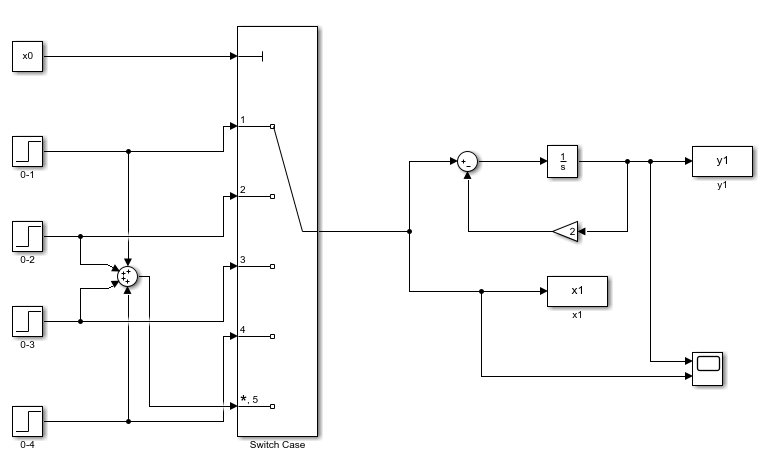

Feito esse esquemático, foi testado cada uma das possibilidades. A seguir segue os gráficos  de x1 pelo tempo e de y1 pelo tempo.

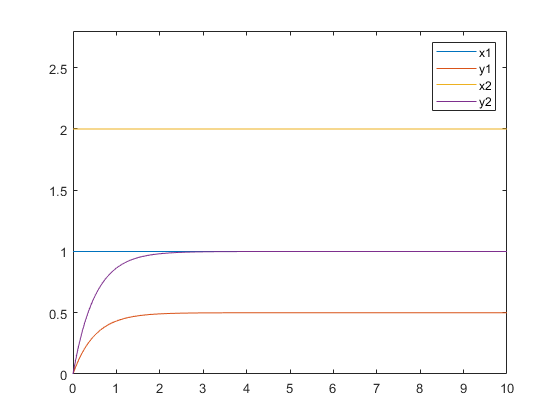

clc
clear all
close all
clc; clear all; close all;
x0=1;
sim("ISC_laboratorio_02_01.slx")
plot(t,x1,t,y1)
hold on
x0=2;
sim("ISC_laboratorio_02_01.slx")
plot(t,x1,t,y1), legend("x1","y1","x2","y2")
axis([0 10 0 2.8])
hold off

Ao analisar o gráfico acima, é possível notar a homogeneidade, visto que:


$$\begin{array}{l}
x=1\to y=0\ldotp 5\\
x=2\to y=1
\end{array}$$


Isto é, ao multiplicarmos nossa variavel x por uma constante c, o valor do y é multiplicado por esta mesma constante y.

**b) Aditivos/Não-Aditivos **

Para verificarmos esse item, continuaremos utilizando o sistema da letra anterior. Para um sistema ser aditivo temos que:


$$f\left(x_1 \right)+f\left(x_2 \right)=f\left(x_1 +x_2 \right)$$


Posto isso, faremos da seguinte forma:


$$f\left(x_{0\;} =1\right)+f\left(x_{0\;} =2\right)+f\left(x_{0\;} =3\right)+f\left(x_{0\;} =4\right)=f\left(x_{0\;} =5\right)$$


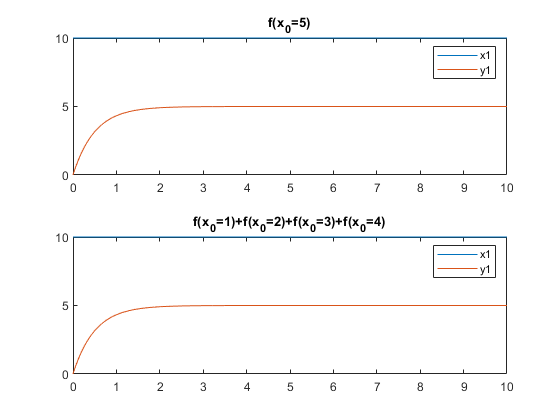

clc
clear all
close all
x0=5;
sim("ISC_laboratorio_02_01.slx")
subplot(2,1,1)
plot(t,x1,t,y1), legend('x1','y1')
title('f(x_0=5)')
x0=1;
sim("ISC_laboratorio_02_01.slx")
x = 0; y = 0;
x = x+x1;
y = y+y1;
x0=2;
sim("ISC_laboratorio_02_01.slx")
x = x+x1;
y = y+y1;
x0=3;
sim("ISC_laboratorio_02_01.slx")
x = x+x1;
y = y+y1;
x0=4;
sim("ISC_laboratorio_02_01.slx")
x = x+x1;
y = y+y1;
subplot(2,1,2)
plot(t,x,t,y)
title('f(x_0=1)+f(x_0=2)+f(x_0=3)+f(x_0=4)'), legend('x1','y1')

Analisando os resultados obtidos a partir dos gráficos, é possível afirmar a aditividade do sistema. Pois


$$f\left(x_{0\;} =1\right)+f\left(x_{0\;} =2\right)+f\left(x_{0\;} =3\right)+f\left(x_{0\;} =4\right)=5$$



$$f\left(x_{0\;} =5\right)=5$$


**c) Lineares/Não-Lineares**

Segundo a literatura, um sistema é linear se o mesmo for homogêneo e aditivo. Pelo item **a** vimos que o sistema é homogêneo. Pelo item **b** tivemos como resultado que o sistema é aditivo. Logo, podemos afirmar que o sistema é linear.

**d) Variantes/Invariantes no tempo**

Para verificarmos essa condição, é ajustado o modelo atual do sistema. Deste modo, temos:

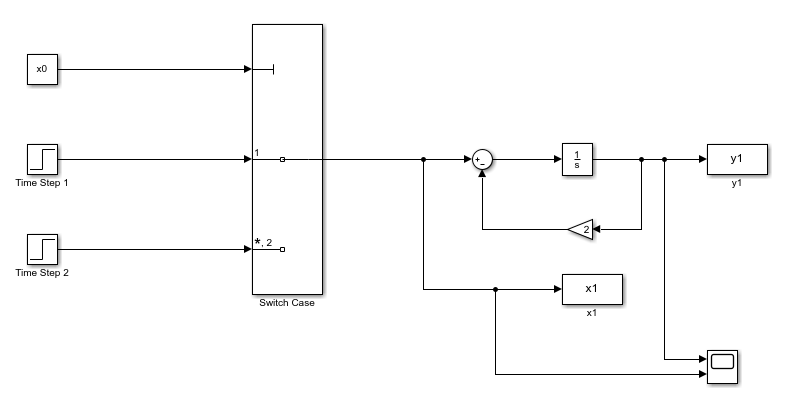

Neste caso, existem apenas dois estados possíveis para a entrada, o time step 1 e o time step 2. Em ambos os casos o step deles é 1, todavia, o que diferencia um do outro é o time step. No time step 1, tem time step igual a 1. Já no time step 2, tem o time step igual a 2.

Posto isso, para verificarmos se o sistema varia no tempo, simularemos com o time step 1 e em seguida o time step 2. Se as respostas forem igual, o sistema não varia o tempo, caso contrário, ele vária.

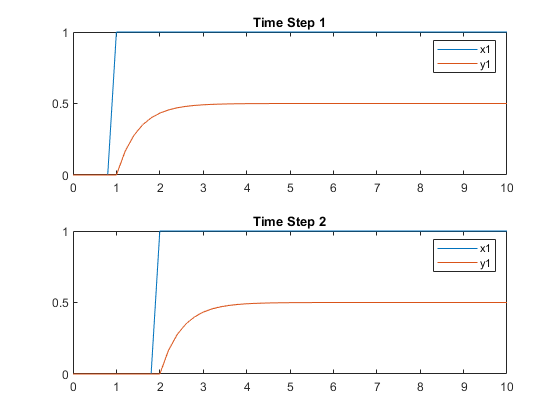

clc
clear all
close all
x0=1;
sim("ISC_laboratorio_02_01_02.slx")
subplot(2,1,1)
plot(t,x1,t,y1), legend('x1','y1')
title('Time Step 1');
x0=2;
sim("ISC_laboratorio_02_01_02.slx")
subplot(2,1,2)
plot(t,x1,t,y1), legend('x1','y1')
title('Time Step 2');

Analisando os gráficos acima, percebe-se que o sistema é invariante no tempo.

### **Sistema 2**


$$2\;\frac{\mathrm{dy}}{\mathrm{dt}}+0,6\sqrt{y}=x\to \frac{\mathrm{dy}}{\mathrm{dt}}=\frac{1}{2}\left(x-0,6\sqrt{y\;}\right)$$


A partir disso, conseguimos modelas essa função do simulink.

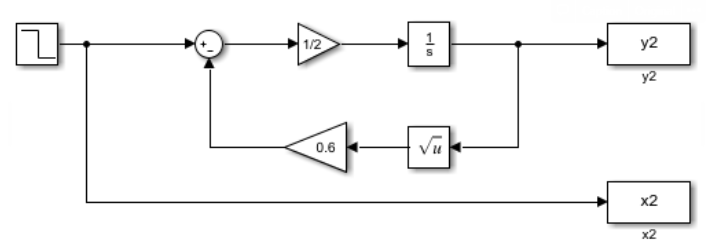

Feito essa modelagem, será verificado a veracidade de cada uns dos itens da questão. 

Como no sistema 1 foi a explicação foi mais explicativa, no sistema 2 e 3, elas serão mais sucintas.

Para a realização dos itens **a**, **b** e **c**, utilizamos o seguintes sistema:

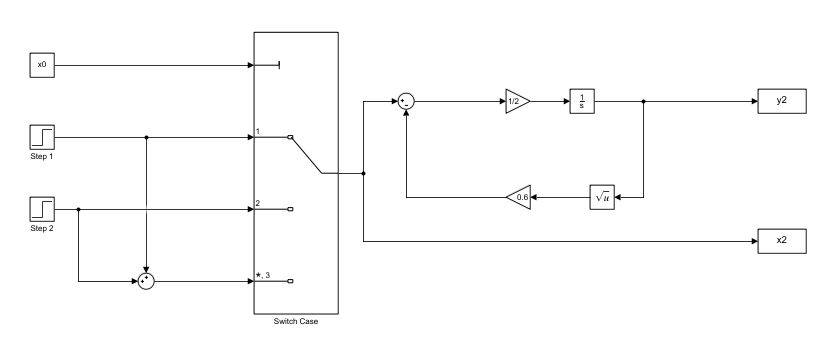

Nesse sistema é tem-se 3 entradas e uma saída. O primeiro pino controla qual entrada será realmente utilizada no modelo. Os pinos 1, 2, 3 são pinos de entrada, sendo que o primeiro pino tem um step de 1, o segundo pino de um step de 2 e o terceiro pino é a soma dos steps de todos os outros pinos, deste modo ficando com 3.

**a) Homogêneos/Não-Homogêneos**

A seguir segue os gráficos  de x1 pelo tempo e de y1 pelo tempo afim de verificar a homogeneidade

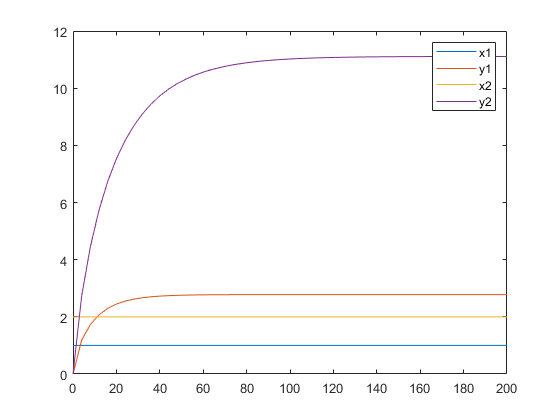

clc
clear all
close all
x0=1;
sim("ISC_laboratorio_02_02.slx")
plot(t,x2,t,y2)
hold on
x0=2;
sim("ISC_laboratorio_02_02.slx")
plot(t,x2,t,y2), legend('x1','y1','x2','y2')
hold off;
axis([0 200 0 12]);

Analisando o gráfico acima, é facil perceber que o sistema não é homogêneo.


$$\begin{array}{l}
x=1\to y=2,77\\
x=2\to y=11,10
\end{array}$$
      
$$\to \frac{1}{2}\not= \frac{2,77}{11,10}$$


Portanto, o sistema não é homogêneo.

**b) Aditivos/Não-Aditivos **

Para verificarmos esse item, continuaremos utilizando o sistema da letra anterior. Para um sistema ser aditivo temos que:


$$f\left(x_1 \right)+f\left(x_2 \right)=f\left(x_1 +x_2 \right)$$


Posto isso, faremos da seguinte forma:


$$f\left(x_{0\;} =1\right)+f\left(x_{0\;} =2\right)=f\left(x_{0\;} =3\right)$$


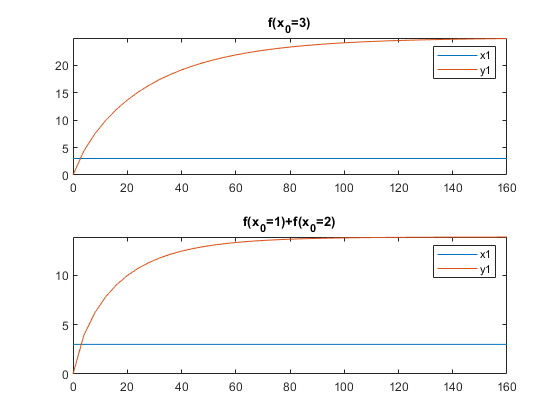

clc
clear all
close all
x0=3;
sim("ISC_laboratorio_02_02.slx")
subplot(2,1,1)
plot(t,x2,t,y2), legend('x1','y1')
title('f(x_0=3)')
axis([0 160 0 inf])
x0=1;
sim("ISC_laboratorio_02_02.slx")
x = 0; y = 0;
x = x+x2;
y = y+y2;
x0=2;
sim("ISC_laboratorio_02_02.slx")
x = x+x2;
y = y+y2;
subplot(2,1,2)
plot(t,x,t,y)
title('f(x_0=1)+f(x_0=2)'), legend('x1','y1')
axis([0 160 0 inf])

Analisando os resultados obtidos a partir dos gráficos, é possível afirmar a não aditividade do sistema. Pois


$$f\left(x_{0\;} =1\right)+f\left(x_{0\;} =2\right)\approx 11$$



$$f\left(x_{0\;} =3\right)\approx 25$$


**c) Lineares/Não-Lineares**

Pelo item **a** vimos que o sistema não é homogêneo, sendo assim, já não pode ser linear.

**d) Variantes/Invariantes no tempo**

Para verificarmos essa condição, é ajustado o modelo atual do sistema. Deste modo, temos:

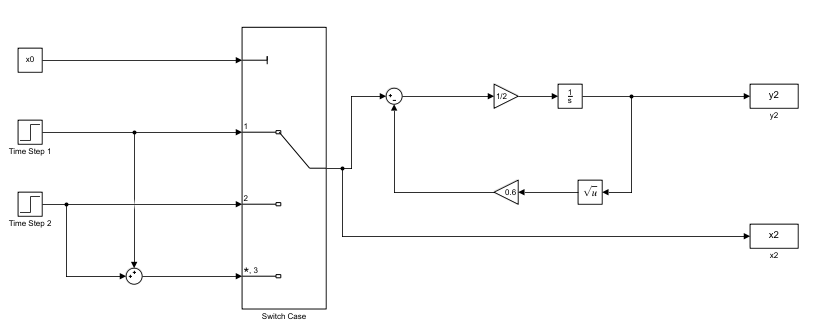

Neste caso, existem apenas dois estados possíveis para a entrada, o time step 1 e o time step 2. Em ambos os casos o step deles é 1, todavia, o que diferencia um do outro é o time step. No time step 1, tem time step igual a 1. Já no time step 2, tem o time step igual a 2.

Posto isso, para verificarmos se o sistema varia no tempo, simularemos com o time step 1 e em seguida o time step 2. Se as respostas forem igual, o sistema não varia o tempo, caso contrário, ele vária.

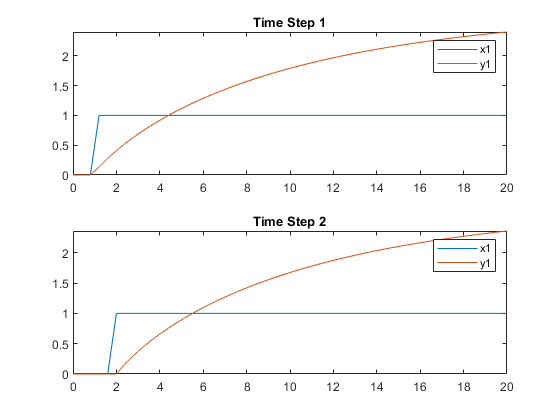

clc
clear all
close all
x0=1;
sim("ISC_laboratorio_02_02_02.slx")
subplot(2,1,1)
plot(t,x2,t,y2), legend('x1','y1')
title('Time Step 1');
x0=2;
sim("ISC_laboratorio_02_02_02.slx")
subplot(2,1,2)
plot(t,x2,t,y2), legend('x1','y1')
title('Time Step 2');

Analisando os gráficos acima, percebe-se que o sistema é invariante no tempo.

### **Sistema 3**


$$\frac{\mathrm{dy}}{\mathrm{dt}}+\left(1+\mathrm{cos}\left(2t\right)\right)y=x\to \frac{\mathrm{dy}}{\mathrm{dt}}=x-\left(1+\mathrm{cos}\left(2t\right)\right)y$$


A partir disso, conseguimos modelas essa função do simulink.

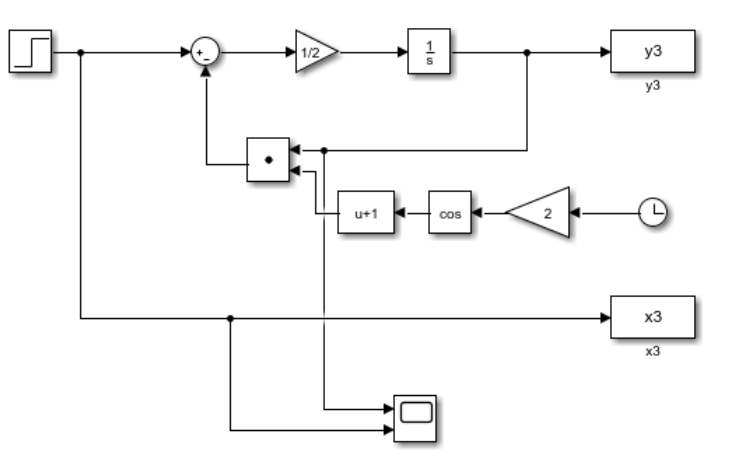

Feito essa modelagem, será verificado a veracidade de cada uns dos itens da questão.

Para a realização dos itens **a**, **b** e **c**, utilizamos o seguintes sistema:

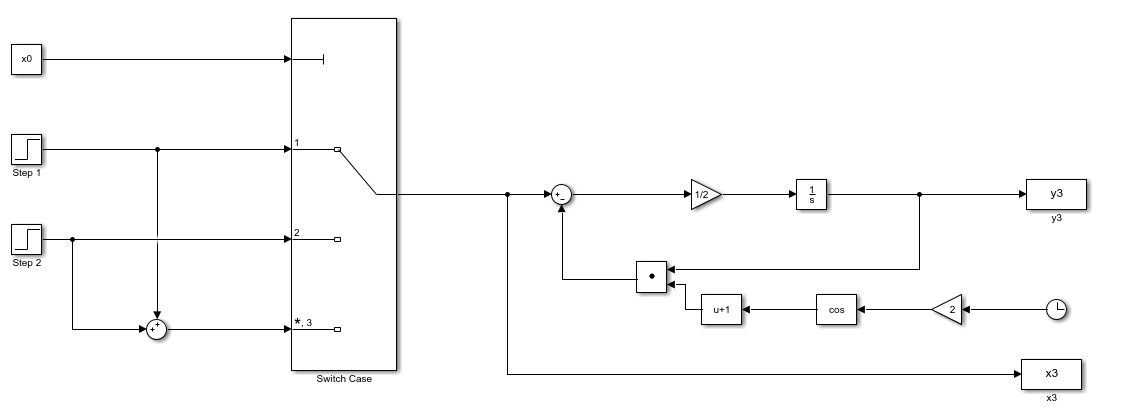

Nesse sistema é tem-se 3 entradas e uma saída. O primeiro pino controla qual entrada será realmente utilizada no modelo. Os pinos 1, 2, 3 são pinos de entrada, sendo que o primeiro pino tem um step de 1, o segundo pino de um step de 2 e o terceiro pino é a soma dos steps de todos os outros pinos, deste modo ficando com 3.

**a) Homogêneos/Não-Homogêneos**

A seguir segue os gráficos  de x3 pelo tempo e de y3 pelo tempo afim de verificar a homogeneidade

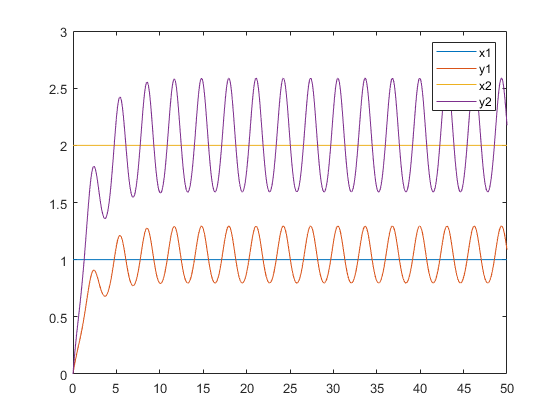

clc
clear all
close all
x0=1;
sim("ISC_laboratorio_02_03.slx")
plot(t,x3,t,y3)
hold on
x0=2;
sim("ISC_laboratorio_02_03.slx")
plot(t,x3,t,y3), legend('x1','y1','x2','y2')
hold off;

Analisando o gráfico acima, é facil perceber que o sistema é homogêneo.


$$\begin{array}{l}
x=1\to y_{p-p} =0,5\\
x=2\to y_{p-p} =1
\end{array}$$
      
$$\to \frac{1}{2}=\frac{0,5}{1}$$


Portanto, o sistema é homogêneo pois a constante proporcinalidade se mantem em ambos os lados da igualdade

**b) Aditivos/Não-Aditivos **

Para verificarmos esse item, continuaremos utilizando o sistema da letra anterior. Para um sistema ser aditivo temos que:


$$f\left(x_1 \right)+f\left(x_2 \right)=f\left(x_1 +x_2 \right)$$


Posto isso, faremos da seguinte forma:


$$f\left(x_{0\;} =1\right)+f\left(x_{0\;} =2\right)=f\left(x_{0\;} =3\right)$$


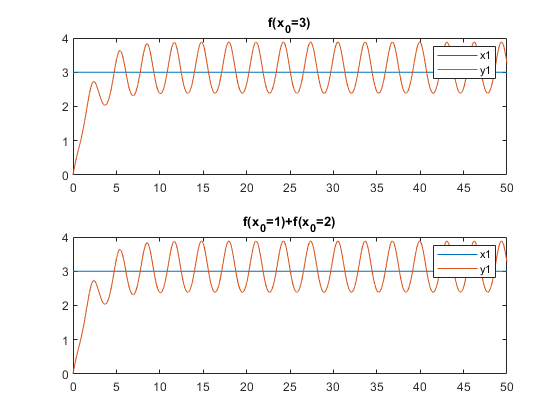

clc
clear all
close all
x0=3;
sim("ISC_laboratorio_02_03.slx")
subplot(2,1,1)
plot(t,x3,t,y3), legend('x1','y1')
title('f(x_0=3)')
% axis([0 160 0 inf])
x = 0; y = 0;
x0=1;
sim("ISC_laboratorio_02_03.slx")
x = x+x3;
y = y+y3;
x0=2;
sim("ISC_laboratorio_02_03.slx")
x = x+x3;
y = y+y3;
subplot(2,1,2)
plot(t,x,t,y)
title('f(x_0=1)+f(x_0=2)'), legend('x1','y1')

Analisando os resultados obtidos a partir dos gráficos, é possível afirmar a aditividade do sistema. Pois


$$f\left(x_{0\;} =1\right)+f\left(x_{0\;} =2\right)\approx 3$$



$$f\left(x_{0\;} =3\right)\approx 3$$


**c) Lineares/Não-Lineares**

Pelo item **a** vimos que o sistema é homogêneo. Pelo item **b** tivemos como resultado que o sistema é aditivo. Logo, podemos afirmar que o sistema é linear.

**d) Variantes/Invariantes no tempo**

Para verificarmos essa condição, é ajustado o modelo atual do sistema. Deste modo, temos:

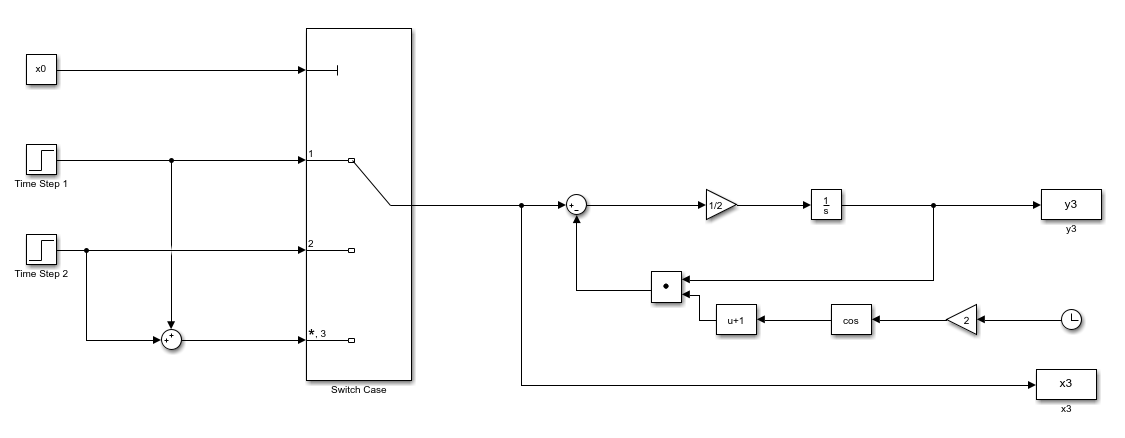

Neste caso, existem apenas dois estados possíveis para a entrada, o time step 1 e o time step 2. Em ambos os casos o step deles é 1, todavia, o que diferencia um do outro é o time step. No time step 1, tem time step igual a 1. Já no time step 2, tem o time step igual a 2.

Posto isso, para verificarmos se o sistema varia no tempo, simularemos com o time step 1 e em seguida o time step 2. Se as respostas forem igual, o sistema não varia o tempo, caso contrário, ele vária.

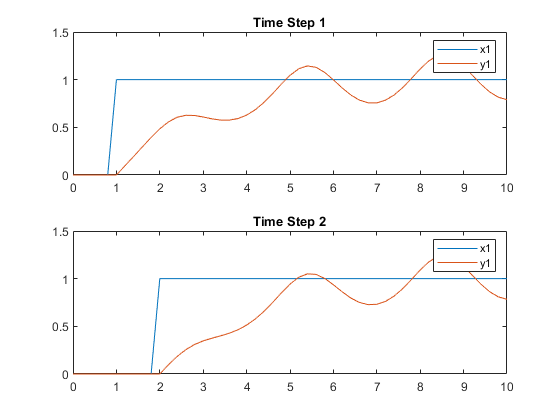

clc
clear all
close all
x0=1;
sim("ISC_laboratorio_02_03_02.slx")
subplot(2,1,1)
plot(t,x3,t,y3), legend('x1','y1')
title('Time Step 1');
x0=2;
sim("ISC_laboratorio_02_03_02.slx")
subplot(2,1,2)
plot(t,x3,t,y3), legend('x1','y1')
title('Time Step 2');

Analisando os gráficos acima, percebe-se que o sistema é variante no tempo. Uma maneira de percebemos isso é a velocidade em que a curva "y1" intercepta a curva "x1". No gráfico "Time Step 1", demora em torno de 4 segundos, já no gráfico "Time Step 2", esse tempo diminui para 3 segundos.